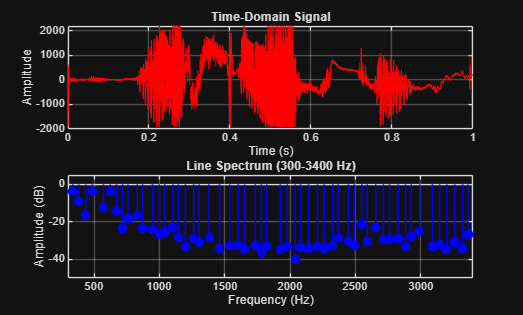

%% Read Audio Signal
signal = readmatrix("C:\Users\liubo\Documents\GitHub projects\FFTVoiceAnalyzer\Test\trustTest.csv");
fs = 10000;       % Sampling frequency
audio = signal;

%% Time Axis
t = (0:length(audio)-1) / fs;

%% FFT Parameters
Nfft = 4096;
window = hann(Nfft);

%% Select Short Frame (quasi-stationary)
frame = audio(1:Nfft) .* window;

%% FFT
X = fft(frame, Nfft);
X = abs(X(1:Nfft/2+1));              % One-sided magnitude
f = (0:Nfft/2) * fs / Nfft;

%% Normalize Spectrum
X = X / max(X);
X_db = 20*log10(X + eps);

%% ---- Band-pass for 300-3400 Hz ----
f_low = 300;
f_high = 3400;

% Indices within desired frequency band
band_idx = (f >= f_low) & (f <= f_high);

% Filter frequency and spectrum
f_band = f(band_idx);
X_db_band = X_db(band_idx);

%% Peak Detection within band
[pks, locs_idx] = findpeaks(X_db_band, f_band, ...
    "MinPeakHeight", -40, ...
    "MinPeakDistance", 40);

%% ---- Plot ----
figure

% Time-domain signal
subplot(2,1,1)
plot(t, audio, 'r', 'LineWidth', 1)
grid on
xlabel("Time (s)")
ylabel("Amplitude")
title("Time-Domain Signal")
xlim([0 1]) 

% Line spectrum (300-3400 Hz)
subplot(2,1,2)
stem(locs_idx, pks, 'b', 'filled', 'LineWidth', 1.2)
grid on
xlabel("Frequency (Hz)")
ylabel("Amplitude (dB)")
title("Line Spectrum (300-3400 Hz)")
ylim([-50 5])
xlim([f_low f_high])